# Create and Customize Feather Plots

Feather plots create arrows emanating from the x-axis and can be used to visualize cartesian, polar and complex values.

### Create Data

Use *pol2cart *in a helper function to generate data for a feather plot. The arrows represent the direction of theta changing from -90 to 90 degrees.

[u,v] = createData();

### Basic Feather Plot

Visualize increasing theta values using `feather`.

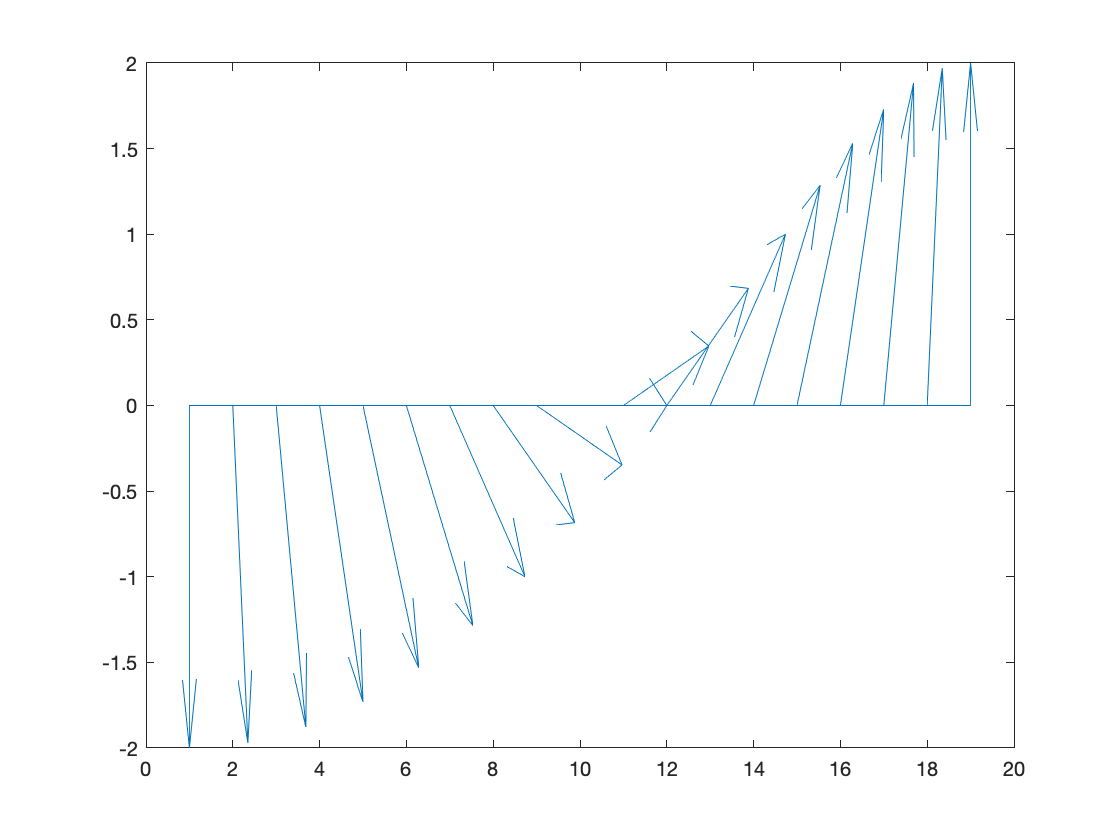

feather(u,v);

## Customization

### Specify Arrow Color

Use the 3rd input to `feather` to specify the arrow color for all arrows. 

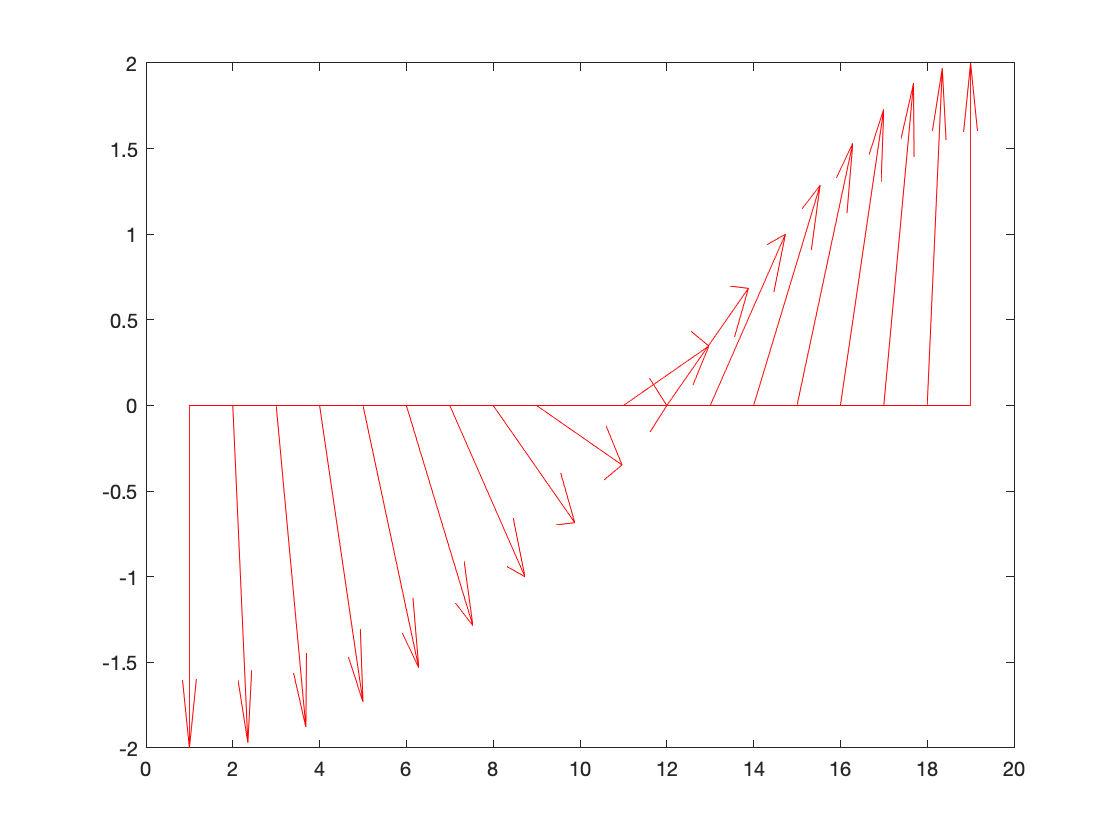

ArrowColor = 'k';

f = feather(u,v,...
    ArrowColor);        % Specify arrow color

### Specify Individual Arrow Appearance

Use dot notation to access the *LineWidth *and *Color *Properties of the Line Object generated from a call to `feather`. The last Line element represents a horizontal line along the x-axis and is excluded from the customization.

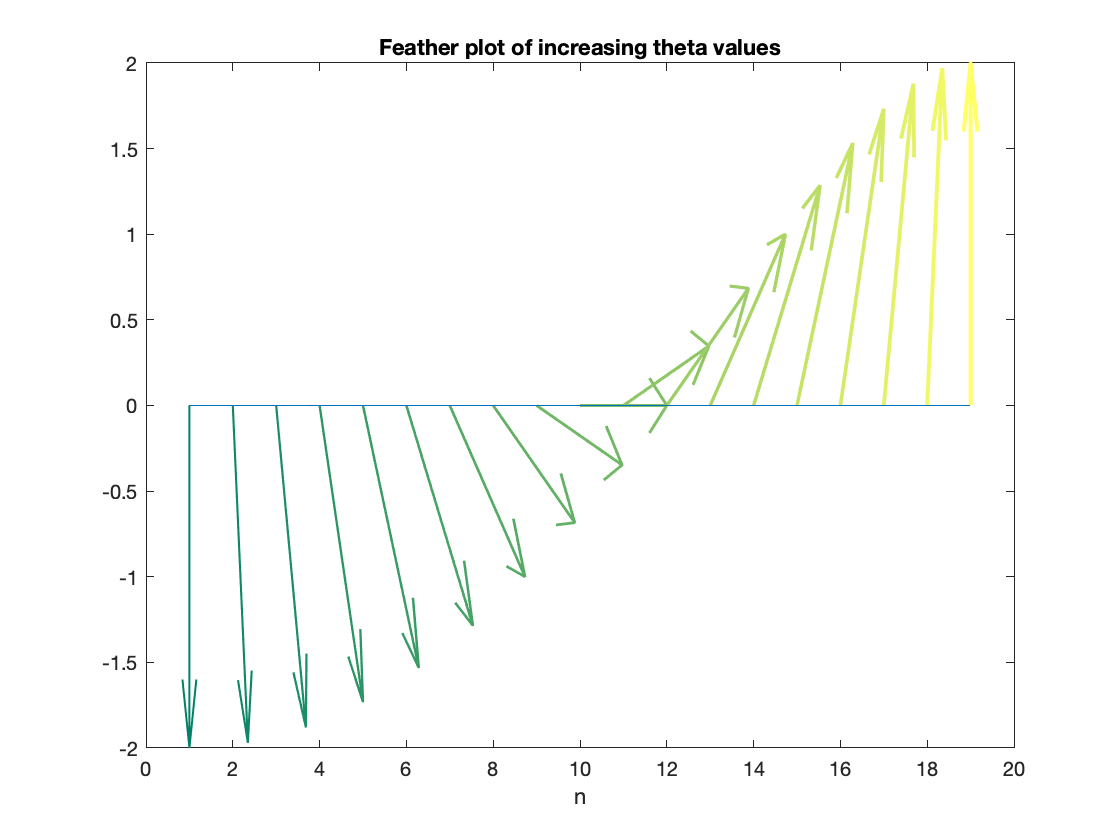

figure
f1 = feather(u,v);
n = length(f1)-1;

LineWidth = linspace(1,2,n);        % Generate vector of increasing LineWidth
Color = colormap(summer(n));        % Generate vector with n elements from the summer colormap

for i = 1:n
    f1(i).LineWidth = LineWidth(i); % Specify LineWidth for each arrow
    f1(i).Color = Color(i,:);       % Specify Color for each arrow
end

xlabel("n");
title("Feather plot of increasing theta values")

## **Additional Information**

### **Get All Line Properties**

Graphics objects in MATLAB have many properties. To see all the properties of a Line Object, uncomment the following line of code.

% get(f(1))

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[feather](https://www.mathworks.com/help/matlab/ref/feather.html)

### Helper Function

This function generates u,v data that represents a theta value changing from -90 to 90 degrees.

function [u,v] = createData()
    theta = (-90:10:90)*pi/180; 
    r = 2*ones(size(theta));
    [u,v] = pol2cart(theta,r);
end

Copyright (c) 2021, The MathWorks, Inc.